# EE451_Homework1_Jacklin

# Lisa Jacklin

# 9/2/2023

## Problem 1 

please note that for each of the pieces of problem 1, the equations will be numbered, while the items to determine will be lettered. Also note that since so much of the work is performed in the command window, for recording perposes, I have choosen to place command line inputs within text format, and items that can be programmed through the .m file within the text sector.

note that n comes from Problem 2

n = -5:1:5;

### problem 1.1

equation: x1(n) = 5delta(n+1) + 10delta(n-3)

using impseq.m,sigshift.m and sigadd.m this equation is inputted

The following lines were written into the command line, note that n given

from Problem 2 which will be plotted later is used as the reference values

for this.

[x1a, n] = impseq(-1, -5,5);

x1a [ 0   0   0   0   1   0   0   0   0   0  0]

[x1b, n] = impseq(3, -5,5);

x1b [0   0   0   0   0   0   0   0   1   0   0]

with this done, sigadd.m function can be used in the command window as

well

[ x1, n] = sigadd (x1a, n, x1b, n)

x1 [0     0     0     0     1     0     0     0     1     0     0]

#### Part a: Length 

after setting up x1 in the command window, the length can be determined.

length(x1);%length = 11

#### Part b: Causal/Anti-causal/Non-Causal 

Since x1 is not zero for all negative or positive values, this is a

non-causal. Please view Problem 2.1 to view the figure that confirms this.

#### Part c: Energy (using energy.m)

just as in the setup, within the command window I use energy.m function to

determine the power over the range n

[ p11] = energy (x1, n)

p11 = 2

#### Part d: Period and is it periodic?

Since delta functions only equal 1 at a single instance during each delta

function, this function is not periodic and thus, does not have a period.

### problem 1.2

Equation: x2(n) = u(n+3) - u(n-3)

using stepseq.m, sigshift.m, and sigsub.m

In the Command window:

[x2a, n] = stepseq(-3, -5, 5)

x2a [0   0   1   1   1   1   1   1   1   1   1]

[x2b, n] = stepseq(3, -5, 5)

x2b [ 0   0   0   0   0   0   0   0   1   1   1]

this gives us the first and second half of x2. Now to add

[x2, n] = sigadd (x2a, n, x2b, n)

x2 [0     0     1     1     1     1     1     1     2     2     2]

#### Part a: Length

length(x2); %length = 11

#### Part b: Causal/Anti-causal/Non-Causal

Since x2 is not zero for all negative or positive values, this is a

non-causal. Please view Problem 2.2 to view the figure that confirms this.

#### Part c: Energy (using energy.m)

in the command window using energy.m

[p2] = energy (x2, n)

p2 = 18

#### Part d: Period and is it periodic?

since a step function is 1 from the offset value or more generally, zero,

there is no pattern to the result shown in figure 2, this this function is

not periodic.

### problem 1.3

equation: x3(n) = 0.5.^n * u(n)

using stepseq.m, sigmult.m

in command window:

x3a = 0.5.^n;

x3a [32.0000   16.0000    8.0000    4.0000    2.0000    1.0000    0.5000    0.2500    0.1250    0.0625    0.0312]

[x3b, n] = stepseq(0,-5, 5)

x3b [0   0   0   0   0   1   1   1   1   1   1]

now to combined them using sigmult.m in command window

[x3, n] = sigmult(x3a, n, x3b, n)

x3 [0  0   0   0    0    1.0000    0.5000    0.2500    0.1250    0.0625    0.0312]

#### Part a: Length

length(x3); %length = 11

#### Part b: Causal/Anti-causal/Non-Causal

since the function x3 is zero until n = 0, this function is thus causal.

#### Part c: Energy (using energy.m)

in command window energy.m is used on x3

[p3] = energy (x3, n)

p3 =     1.3330

#### Part d: Period and is it periodic?

there is no patern in this function, and this is an exponential function

past n = 0 thus, this function is not periodic.

### problem 1.4

equation: x4(n) = 2.^n * u(n)

using stepseq.m, sigmult.m

x4a = 2.^n

x4a [0.0312    0.0625    0.1250    0.2500    0.5000    1.0000    2.0000    4.0000    8.0000   16.0000   32.0000]

[x4b, n] =  stepseq(0,-5, 5)

x4b [ 0   0   0   0   0   1   1   1   1   1   1]

[x4, n] = sigadd(x4a, n, x4b, n)

x4 [0.0312    0.0625    0.1250    0.2500    0.5000    2.0000    3.0000    5.0000    9.0000   17.0000   33.0000]

#### Part a: Length

length(x4); %length = 11

#### Part b: Causal/Anti-causal/Non-Causal

since this signal begins at n = -1, and n less than -1 equals zero,

although only off by a single point, results in a non-causal signal.

#### Part c: Energy (using energy.m)

in command window energy.m is used on x4

[p4] = energy (x4, n)

p4 =  1.4973e+03

#### Part d: Period and is it periodic?

since this function is exponential, this is non periodic.

### problem 1.5

equation: x5(n) = 10*cos[2pin + pi/3] + 5sin[2pin]

using sigadd.m, and the cos and sin functions built into MATLAB

x5a = 10.*cos(2*pi*n + pi/3);

x5a [5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000]

x5b = 5.* sin(2*pi*n);

x5b [0.6123    0.4899    0.3674    0.2449    0.1225         0   -0.1225   -0.2449   -0.3674   -0.4899   -0.6123]

[x5, n] = sigadd(x5a, n, x5b, n)

x5 [5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000]

#### Part a: Length

length(x5); %length = 11

#### Part b: Causal/Anti-causal/Non-Causal

just as the rest, this signal is non-causal as it does not change to be

zero at any point within the signal.

#### Part c: Energy (using energy.m)

[p5] = energy (x5, n)

p5 =  275.0000

#### Part d: Period and is it periodic?

since this function includes sin and cos this signal is periodic with a

period of pi.

### problem 1.6

equation: x6(n) = 5*exp[jpin + pi/6]

using exponent built into MATLAB

x6 = 5*exp(j*pi*n + pi/6);

x6 [-8.4405 - 0.0000i   8.4405 + 0.0000i  -8.4405 - 0.0000i   8.4405 + 0.0000i  -8.4405 - 0.0000i   8.4405 + 0.0000i        -8.4405 + 0.0000i   8.4405 - 0.0000i  -8.4405 + 0.0000i   8.4405 - 0.0000i  -8.4405 + 0.0000i ] 

notice how there is an imaginary value for each of these items.

#### Part a: Length

length(x6) = 11;

#### Part b: Causal/Anti-causal/Non-Causal

Since this signal is neither zero for n less than zero, or n greater than zero, this signal is non causal.

#### Part c: Energy (using energy.m)

[p6] = energy (x6, n)

p5 = 7.8365e+02 - 3.7865e-29i

#### Part d: Period and is it periodic?

Note that x6 is built of imaginary and real parts, thus, if we consider real(x6) using matlab to determine the real values we can see the real part and find the period from here, which should be pi.

x6d = real(x6);

stem(x6d)

### Problem 2: plot the signals in part 1 given n = -5...5

note that this range for n is used to provide answers to problem 1 as well. Note that the n range   writen above with Problem 1 for values to compute with the functions built.


% %Problem 2.1
% figure; stem(n, x1);
% xlabel('time (n)'); ylabel("Amplitude")
% title('Stem Wave of x1 Problem 1.1')
% 
% %Problem 2.2
% figure; stem(n, x2);
% xlabel('time (n)'); ylabel("Amplitude");
% title('Stem wave of x2 Problem 1.2')
% 
% %Problem 2.3
% figure; stem(n, x3);
% xlabel('time (n)'); ylabel("Amplitude");
% title('Stem wave of x3 Problem 1.3')
% 
% %Problem 2.4
% figure; stem(n, x4);
% xlabel('time (n)'); ylabel("Amplitude");
% title('Stem wave of x4 Problem 1.4')
% 
% %Problem 2.5
% figure; stem(n, x5);
% xlabel('time (n)'); ylabel("Amplitude");
% title('Stem wave of x5 Problem 1.5')
% 
% %Problem 2.6
% figure; stem(n, real(x6));
% xlabel('time (n)'); ylabel("Amplitude");
% title('Stem wave of x6 Problem 1.6')

## Problem 3: DSP:P&M 2.1

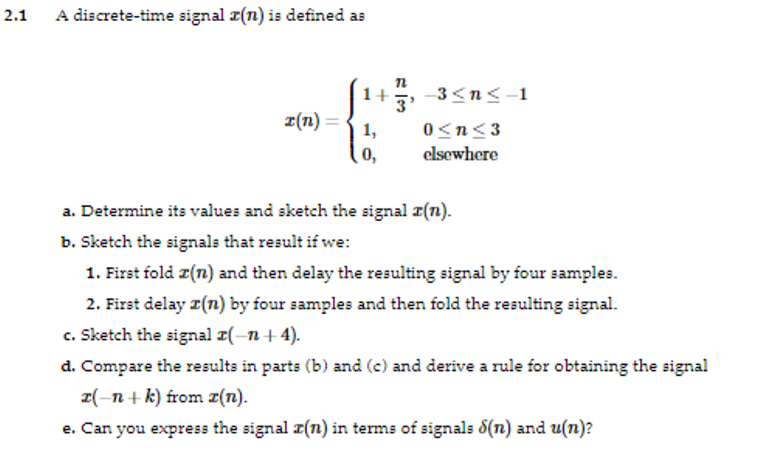

### Part a. Determine its values and Sketch the signal x(n)

%given the values shown for x(n) in 2.1 n is built
%n = -5:1:5; %note that n given in problem 2 works here so now to insert values for x!
% x = [0 0 0 0.3333 0.6666 1 1 1 1 0 0 ]; %note that I determined values through basic math and equations shown above
% figure; stem(n, x);
% xlabel("time (n)"); ylabel("Amplitude(x)");
% title("Problem 3 (DSP 2.1) Signal x(n) sketch");

### Part b. Sketch the signal with two different signal adjustments.

#### b.1: Fold and delay by 4

in the command window using sigfold and sigshift.m functions:

[xb2a, n] = sigfold (x, n);

xb2a [0         0    1.0000    1.0000    1.0000    1.0000    0.6666    0.3333         0         0         0]

[xb2b, nxb] = sigshift(xb2a, n, 4);

xb2b = [0 0 0 0 0 0 1.0000 1.0000 1.0000 1.0000 0.6666 ]

% figure; stem(n, xb2b);
% xlabel('time (n)'); ylabel("Amplitude (x)");
% title("Problem 3.b1 Fold and Delay by 4 Signal Results");

#### b.2: Delay by 4 then fold results

in the command window, similar to how performed above, but oposite order:

[xb, n] = sigshift(x, n, 4)

xb = [0 0 0 0 0 0 0.333 0.666 1 1 1 ]

[xbb2, n] = sigfold (xb, n);

xbb2 = [1.0000    1.0000    1.0000    0.6660    0.3330         0         0         0         0         0         0]

% figure; stem (n, xbb2);
% xlabel('time (n)'); ylabel("Amplitude (x)");
% title("Problem 3.b2 Delay by 4 then Fold Signal Results");

### part c.Sketch the signal x(- n + 4)

note that this signal is the same as what was built in part b.1 with the fold creating x(-n) and the shift resulting in x(-n +4);

% figure; stem(n, xb2b);
% xlabel('time (n)'); ylabel("Amplitude (x)");
% title("Problem 3.c x(-n +4)");

### part d. compare the results in parts b and c and derive a rule for obtaining the signal x(-n +k) from x(n)

When comparing the results of part b and c, it becomes obvious that although they are performing the same tasks although different orders, the result is different as seen between part b.2 and part c where the tail end of the signal is displayed while the beginning impulse display is seen in part c.

For this, two rules are created to make this adjustment to the signal, sigfold(x, n) which would give x(-n) and sigshift.m which gives x(n +- k).

#### Sigfold.m

function [y, n] = sigfold (x, n)

% y(n) = x (-n)

% --------------------------

% This flips the index values of n

n = -fliplr(n);

y = fliplr(x);

#### Sigshift.m

function [y, n] = sigshift(x, m, k)

% y(n) = x(n + k)

% -------------------

% k is the shifting value

% single signal shift

if k>0

    disp(‘Positive’);

    n1 = n(1):n(end)+k;

    x1 = [zeros(1,k) x];

else

    disp(‘Negative’);

    n1 = n(1)+k:n(end);

    x1 = [x zeros(1,abs(k))]; % abs is for absolute value of (k) because quantity can never be (-ve) negative %

end

### part e. Can you express the signal x(n) in terms of signals delta(n) and u(n)?

Given the base signal x(n), most spots would result in an impulse or step signal which are labeled as ex1, ex2, etc.

The following is run in the command window.

 [ex1,n] = stepseq(0 ,0, 3) %gives from 0 to 3

n1 = 0:1:3;

[ex2a, n] = impseq(-2, -5,5) %this is the first pulse higher than n = -3

ex2 = 0.333* ex2a;

[ex3a, n] = impseq(-1, -5, 5) %gives the second pulse at n = -1

ex3 = 0.666*ex3a;

%now all these pulses need to be combined

[exa, n] = sigadd(ex1, n1, ex2, n);

[exb, n] = sigadd(ex3, n, exa, n);

exb = [0         0         0    0.3330    0.6660    1.0000    1.0000    1.0000    1.0000         0         0]

Which, to make sure that this matches as expected, is displayed:

% figure; stem(n, exb);
% xlabel("time (n)"); ylabel("Amplitude(x)");
% title("Problem 3 part e Signal x(n) in delta and step");

## Problem 4: DSP:P&M 2.2

## 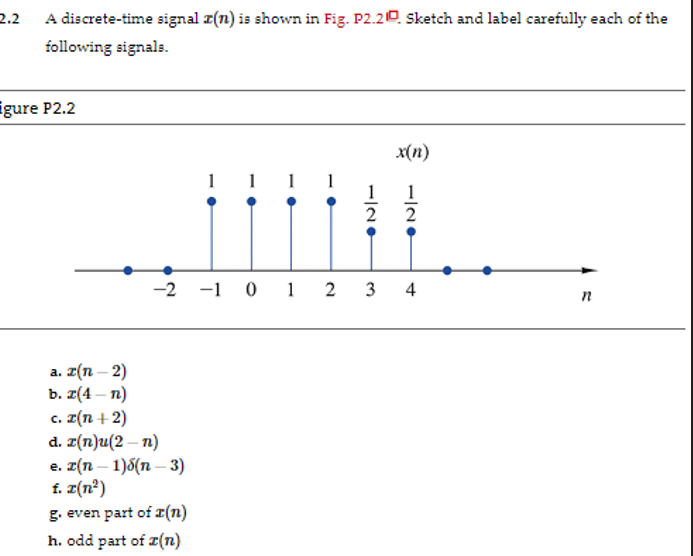

In the command window, the base x(n) function and adjusted n values to match what the figure p2.2 displays.

x22 = [0 0 1 1 1 1 0.5 0.5 ];

n22 = -2:1:4;

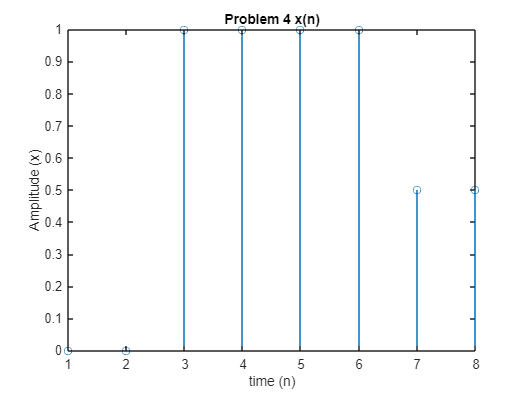

%original x(n) from the problem above for comparisons
figure; stem(x22);
xlabel("time (n)"); ylabel("Amplitude (x)")
title("Problem 4 x(n)")

### Problem 4.a x(n -2)

[x22a, n22a] = sigshift(x22, n22, 2);

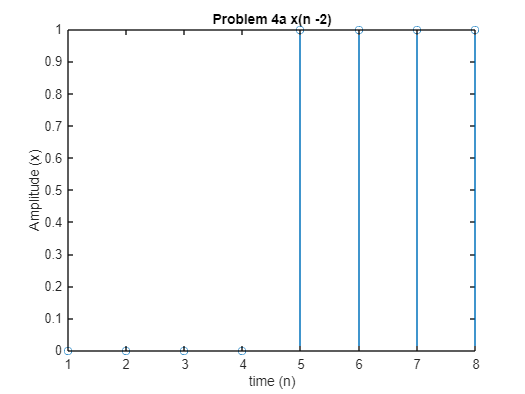

x22a = [0 0 0 0 1 1 1 1 ];
figure; stem(x22a);
xlabel("time (n)"); ylabel("Amplitude (x)")
title("Problem 4a x(n -2)")

### Problem 4.b x(4-n)

[x22b, n22] = sigshift(x22, n22, 4) % x (4 + n)

x22b = [1 1 0.5 0.5 0 0 0 0]

[x22b, n22] = sigfold (x4b, n);

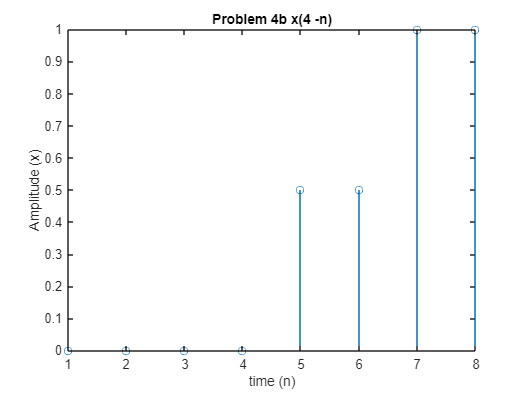


x22b = [ 0         0         0         0    0.5000    0.5000    1.0000    1.0000];figure; stem(x22b);
xlabel("time (n)"); ylabel("Amplitude (x)");
title("Problem 4b x(4 -n)");

### Problem 4.c x(n + 2)

[x22cm n22] = sigshift(x22, n22, -2);

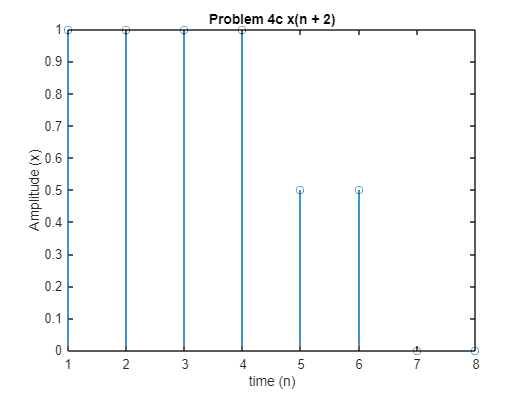

x22c = [1 1 1 1 0.5 0.5 0 0];
figure; stem(x22c);
xlabel("time (n)"); ylabel("Amplitude (x)");
title("Problem 4c x(n + 2)");

### Problem 4.d x(n) * u(2-n)

[x22d4, n] = stepseq(2,-2, 4); %note that this needs to be folded as well to get 2-n

x22d4 = [ 0   0   0   0   1   1   1]

[x22da, n] = sigfold(x22d4, n);

x22da = [ 1   1   1   0   0   0   0];

[x22d, n] = sigadd(x22da, n, x22, n);

x22d = []
figure; stem(x22d);
xlabel("time (n)"); ylabel("Amplitude (x)");
title("Problem 4d x(n) * u(2-n)");

### Problem 4.e x(n-1) * delta(n-3)

figure; stem(x22d);
xlabel("time (n)"); ylabel("Amplitude (x)");
title("Problem 4d x(n) * u(2-n)");

### Problem 4.f x(n^2)

figure; stem(x22d);
xlabel("time (n)"); ylabel("Amplitude (x)");
title("Problem 4d x(n) * u(2-n)");

### Problem 4.g even part of x(n)

figure; stem(x22d);
xlabel("time (n)"); ylabel("Amplitude (x)");
title("Problem 4d x(n) * u(2-n)");

### Problem 4.h odd part of x(n)

figure; stem(x22d);
xlabel("time (n)"); ylabel("Amplitude (x)");
title("Problem 4d x(n) * u(2-n)");

## Problem 5: DSP: P&M 2.2